# Pendulum DE Examples

### First Order Approximation Using dsolve

Solving by hand... 


$$-g\;\theta =R\;\theta^¨$$
        
$$\theta =A\;\mathrm{cos}\;\mathrm{Bt}$$
        
$$B=\sqrt{\frac{g}{R}}$$
     
$$\theta =A\;\cos \;\sqrt{\frac{g}{R}}\textrm{t}$$
      
$$\theta =\theta_{\mathrm{max}} \;\cos \;\sqrt{\frac{g}{R}}\mathrm{t}$$


 Using dsolve

syms g L q_o q(t);
% Solving first order approx analytically
Dq = diff(q, t);
D2q = diff(q, t, 2);
equ = D2q == - (g/L)*(q);
% Specify initial conditions q(o), Dq(0)
cond = [q(0) == theta_0, Dq(0) == 0];
dsolve(equ, cond); % dsolve analytical solution

% Graph analytical solution
theta_0 = pi/3; % radians
theta_dot_0 = 0; % rad/s
g = 9.8; % m/s
L = 4; % m
t_span = [0, 10];
equ = D2q == - (g/L)*(q);
cond = [q(0) == theta_0, Dq(0) == theta_dot_0];
theta = dsolve(equ,cond);

clf
hold on
set(groot,'DefaultAxesFontSize',18)
fplot(theta,t_span,'-.r','DisplayName','1st order')
xlabel('time in seconds')
ylabel('Degrees in radians')

### Second Order Approximation Using ODE45

 Second Order Approximation Using Taylor: $-g\left(\left(\theta \right)-\frac{1}{6}{\left(\theta \right)}^3 \right)=R\theta^¨$

[t, y] = ode45(@ODE45Pend2ndOrder, t_span, ...
    [theta_0; theta_dot_0]);
plot(t,y(:,1),'-.bs','DisplayName','2st order')

### Full Solution Using ODE45

 Full Solution:  $-\mathrm{gsin}\theta =R\theta^¨$

Constants and Initial Conditions

[t, y] = ode45(@ODE45PendFull, t_span,...
    [theta_0;theta_dot_0]);
plot(t,y(:,1),'-k*','DisplayName','Full Solution')

### Pendulum with drag


$$\theta^¨ \;\left(t\right)=-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\mathrm{sin}\left(\theta \left(t\right)\right)$$
             
$$\overrightarrow{r} \left(t\right)=\left\lbrack \begin{array}{c}
V_0 \;\cos \left(\theta_0 \;t\right)\\
-\frac{1}{2}{\textrm{gt}}^2 +V_0 \sin \left(\theta_0 t\right)
\end{array}\right\rbrack$$


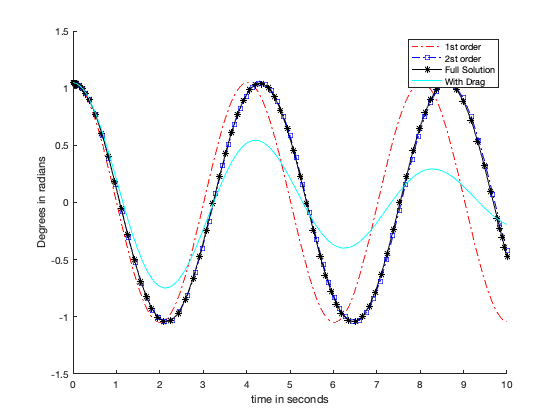

theta_0 = pi/3;
theta_dot_0 = 0;
[t, y] = ode45(@ODE45PendWDrag, t_span, ...
    [theta_0; theta_dot_0]);
plot(t, y(:,1),'-c', 'DisplayName','With Drag')
legend
hold off